# EE 523 Power System Stability and Control Algorithms

### Preamble and Control Inputs

tic;
if strcmp(getenv('USERNAME'), 'aryan')
    cd C:\Users\aryan\Documents\documents_general\dablab_files\ee521_and_ee523
end

you may continue as usual

addpath functions\
systemName = "ieee11-caseTwo-"

systemName = "ieee11-caseTwo-"

powerFlowMethod =  "NRPF" 

powerFlowMethod = "NRPF"

modelType = "Type2" %Synchronous Machine Model Type

modelType = "Type2"

useReducedLoadsForPowerFlow = false; %only needed if Type2 or 3
displayYGen = false; %Show YGen
displayYNet = false; %Show YNet
saveYGenMatrices = true; %Save YNet, Ygr, Yrg, Yrr, YGen
showInternalMatrices = false; %Show Ygg, Ygr, Yrg, Yrr
numIterations = 50; %I don't wait for the system to converge, 
printPowerFlowConvergenceMessages = false;
% neither do I care if the system converges earlier.
toleranceLimit = 1e-3; %mean of absolute values of 
% corrections should be less than this for convergence to be achieved.
displayRawData = false;
displayRawDataForYNet = false;
displayYBus = false;
displayTables = false; %show busData, branchData ybus, 
% basically data structures which are not the final output.
printJacobians = false  ; %Print Jacobians during NRPF iterations? Does not work if displayTables is off.
printMismatches = false; %Print Mismatches during NRPF iterations? Does not work if displayTables is off.
printCorrections = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
showPlots = false;
displayResults = true;
reducedBranchColumnsCDFReading = true; 
showImages = true; %might add iteration specific images later. 
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.

folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system
folder_processedData = "processedData/";
% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranchNet] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading);

Optionally display the system data.

if displayTables && displayRawData
    displayRawDataAsTables(busData, branchData, N, numBranchNet);
end

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table `for Type I OR Make $Y_{Bus}$ (reduced loads only), $Y_{Net}$, $Y_{Gen}$ for Type II and Type III models.

### Then Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

[~, ~, ~, ~, ...
        ~, listOfPVBuses, ~, nPV, ...
        ~] = initializeVectors(busData, MVAb);

#### Synchronous Machine Parameters

kVB = 230;
kVB_Gen = 20;
kVB_Gen_side = 20;
MVAb_Gen = 900;

Xd_prime_vals = 0.3* ones(nPV+1, 1) * (MVAb/MVAb_Gen) * (kVB_Gen/kVB_Gen_side)^2;
Xq_prime_vals = 0.55* ones(nPV+1, 1) * (MVAb/MVAb_Gen) * (kVB_Gen/kVB_Gen_side)^2; 

if ~strcmp(modelType, "Type1")
    X_prime_vals = 0.5* (Xd_prime_vals + Xq_prime_vals)

    [busDataNet, busDataReducedLoads, busDataGen, branchDataNet, NNet, numBranchNet] = ...
        modifyForYNet(busData, branchData, N, ...
        numBranchNet, listOfPVBuses, nPV, ...
        X_prime_vals, MVAb, displayRawDataForYNet);

    if useReducedLoadsForPowerFlow
        [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busDataReducedLoads, branchData); %#ok<*UNRCH>

        
        [PSpecified, QSpecified, V, delta, ...
            listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
            listOfNonSlackBuses] = initializeVectors(busDataReducedLoads, MVAb);
    else

        [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);

        [PSpecified, QSpecified, V, delta, ...
            listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
            listOfNonSlackBuses] = initializeVectors(busData, MVAb);
    end
    
    [yNet, ~, ~, ~, ~, ENet] = ybusGenerator(busDataNet, branchDataNet);

    
    [yGen, BMatrixGen, EGen, listOfResidualBuses] = constructYGen(yNet, listOfPVBuses, NNet, displayYNet, showInternalMatrices, displayYGen, saveYGenMatrices);
    

    [P, Q, V, delta] = solveForPowerFlow(PSpecified, QSpecified, V, delta, ybus, BMatrix, E, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, numIterations, toleranceLimit, powerFlowMethod, displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);
    
else
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);

    [PSpecified, QSpecified, V, delta, ...
        listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
        listOfNonSlackBuses] = initializeVectors(busData, MVAb);

    [P, Q, V, delta] = solveForPowerFlow(PSpecified, QSpecified, V, delta, ybus, BMatrix, E, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, numIterations, toleranceLimit, powerFlowMethod, displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);

end

X_prime_vals =     0.0472
    0.0472
    0.0472
    0.0472


Convergence using NRPF achieved in 4 iterations.



ybusTable = array2table(ybus, VariableNames=[string(1:N)], RowNames=[string(1:N)]);

if displayTables && displayYBus
    % display(ybusTable);
    format shortG
    disp(sparse(ybus));
    format default
end

### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

resultTable = displayPowerFlowResults(P, Q, V, delta, displayResults);

resultTable = 11×4 table
                   P             Q           V        delta  
              ___________    __________    ______    ________

    Bus 1          6.9125       0.97628      1.03           0
    Bus 2          6.9999       0.28743      1.01    -0.16305
    Bus 3            7.19        1.3188      1.03    -0.33186
    Bus 4          6.9999       0.95997      1.01     -0.5076
    Bus 5     -0.00032164    0.00013155    1.0203    -0.10987
    Bus 6      6.1618e-05    0.00041555    1.0118    -0.27749
    Bus 7         -9.6704       -0.9992    1.0213    -0.41277
    Bus 8     -0.00019623    0.00056996    1.0095    -0.55261
    Bus 9         -17.669      -0.99909    1.0025    -0.76451
   

plotPowerFlowResults(showPlots, V, busData, systemName, powerFlowMethod, delta);

### Post-Powerflow

listOfGenBuses = [1; listOfPVBuses];
P_i_Gen = P(listOfGenBuses);
Q_i_Gen = Q(listOfGenBuses);
S_i_Gen = P_i_Gen + 1i*Q_i_Gen;

P_G_Gen = P_i_Gen + busData.PL(listOfGenBuses)/MVAb;
P_m_Gen = P_G_Gen;
Q_G_Gen = Q_i_Gen + busData.QL(listOfGenBuses)/MVAb;
S_G_Gen = P_G_Gen + 1i*Q_G_Gen;

V_Gen = V(listOfGenBuses);
delta_Gen = delta(listOfGenBuses);
[V_Gen_Cartesian_Real, V_Gen_Cartesian_Imag] = pol2cart(delta_Gen, V_Gen);
V_Gen_Cartesian = V_Gen_Cartesian_Real + 1i*V_Gen_Cartesian_Imag;
I_Gen = conj(S_G_Gen./V_Gen_Cartesian);
EprimeCartesian = V_Gen_Cartesian + 1i*X_prime_vals.*I_Gen;
[thetaVals, E_primeVals] = cart2pol(real(EprimeCartesian), imag(EprimeCartesian));
rowNames = arrayfun(@(i) sprintf('Gen %d', i), 1:nPV+1, 'UniformOutput', false);

resultGen = array2table([E_primeVals, thetaVals], 'VariableNames', {'E''', 'theta'}, 'RowNames', rowNames)

resultGen = 4×2 table
               E'        theta  
             ______    _________

    Gen 1    1.1205      0.28675
    Gen 2    1.0745      0.14645
    Gen 3    1.1392    -0.038304
    Gen 4    1.1045     -0.20676


syms t
theta = sym('theta', [nPV+1, 1]);
% theta = arrayfun(@(i) str2sym(sprintf('theta_%d(t)', i)), 1:nPV+1, 'UniformOutput', false);
% theta = transpose([theta{:}]);

theta(1) = 0;
omega = sym('omega', [nPV+1, 1]);
% omega = arrayfun(@(i) str2sym(sprintf('omega_%d(t)', i)), 1:nPV+1, 'UniformOutput', false);
% omega = transpose([omega{:}]);
PG = sym('P_G', [nPV+1, 1]);
w_s = 2*pi*60;
H = [6.5; 6.5; 6.175; 6.175];
K_D = ones(nPV+1, 1);

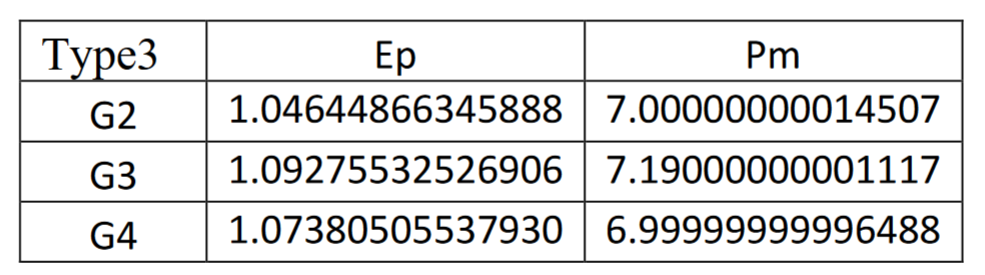

E_primeValsOfficial = [1.10; 1.04644866345888; 1.09275532526906; 1.07380505537930];
% for i = listOfPVBuses'
%     PG(i) = real( yGen(i, i) ) * abs( E_primeVals(i) )^2;
%     for k = EGen{i}
%         PG(i) = PG(i) + abs( yGen(i, k) * E_primeVals(i) * E_primeVals(k) ) * cos( angle(yGen(i, k)) + theta(k) - theta(i) );
%     end
% end
for i = listOfPVBuses'
    PG(i) = real( yGen(i, i) ) * abs( E_primeValsOfficial(i) )^2;
    for k = EGen{i}
        PG(i) = PG(i) + abs( yGen(i, k) * E_primeValsOfficial(i) * E_primeValsOfficial(k) ) * cos( angle(yGen(i, k)) + theta(k) - theta(i) );
    end
end
PG2 = PG(listOfPVBuses);
theta2 = theta(listOfPVBuses);
theta2Vals = thetaVals(listOfPVBuses);
omega2 = omega(listOfPVBuses);
P_m2 = P_m_Gen(listOfPVBuses);
H2 = H(listOfPVBuses);
K_D2 = K_D(listOfPVBuses);
ode_theta = diff(theta2) == (omega2-1)*w_s;
ode_theta0 = 0 == rhs(ode_theta);

%MATlAB solve function outputs a structure containing variables as
%fieldnames and the numerical solutions as field values
%the dance below is used to extract just those numeric values from the
%structure. Seems awfully hard for a seemingly commonplace requirement.
omegaSols = struct2cell(solve(ode_theta0, omega2));
omegaVals = double([omegaSols{:}])';
ode_omega = diff(omega2) == (P_m2 - PG2 - K_D2.*(omega2 - 1))*0.5./H2;
ode_Type3 = [rhs(ode_theta); rhs(ode_omega)]

$$ode\_Type3 = \left(\begin{array}{c} 376.9911\,\omega_{2}-376.9911\\ 376.9911\,\omega_{3}-376.9911\\ 376.9911\,\omega_{4}-376.9911\\ 0.4967-0.1077\,\cos\left(\theta_{4}-\theta_{2}+0.7131\right)-0.0788\,\cos\left(\theta_{3}-\theta_{2}+0.7411\right)-0.7167\,\cos\left(\theta_{2}-1.3609\right)-0.0769\,\omega_{2}\\ 0.5038-0.4404\,\cos\left(\theta_{4}-\theta_{3}+1.1314\right)-0.0829\,\cos\left(\theta_{2}-\theta_{3}+0.7411\right)-0.1334\,\cos\left(\theta_{3}-0.8011\right)-0.0810\,\omega_{3}\\ 0.3765-0.4404\,\cos\left(\theta_{3}-\theta_{4}+1.1314\right)-0.1134\,\cos\left(\theta_{2}-\theta_{4}+0.7131\right)-0.1824\,\cos\left(\theta_{4}-0.7730\right)-0.0810\,\omega_{4} \end{array}\right)$$

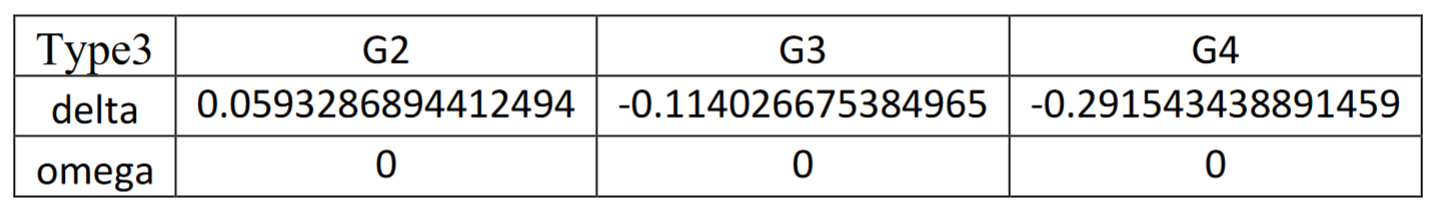

theta2OfficialVals = [0.0593286894412494; -0.114026675384965; -0.291543438891459]

theta2OfficialVals =     0.0593
   -0.1140
   -0.2915


% subs(ode_Type3, [theta2, omega2], [theta2Vals, omegaVals])
subs(ode_Type3, [theta2, omega2], [theta2OfficialVals, omegaVals])

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0.0619\\ 0.0361\\ 0.0380 \end{array}\right)$$


J = jacobian(ode_Type3, [theta2; omega2]);
Je = double(subs(J, [theta2, omega2], [theta2Vals, omegaVals]))

Je =          0         0         0  376.9911         0         0
         0         0         0         0  376.9911         0
         0         0         0         0         0  376.9911
   -0.7512    0.0416    0.0379   -0.0769         0         0
    0.0663   -0.5271    0.3615         0   -0.0810         0
    0.0992    0.4243   -0.6751         0         0   -0.0810


[V, D, W] = eig(Je);
lambdas = diag(D)

lambdas =   -0.0405 +19.4188i
  -0.0405 -19.4188i
  -0.0385 +16.9488i
  -0.0385 -16.9488i
  -0.0405 + 8.4886i
  -0.0405 - 8.4886i


% v1 = V(:, 1);
% Je*v1 - v1*D(1, 1)
W_T = W';
% wT_1 = W_T(1, :);
% wT_1*Je - D(1, 1)*wT_1
p = zeros(size(Je, 1), 1);
for i = 1:length(p)
    p(i) = dot(V(:, i), W_T(i, :))/( max(abs(V(:, i))) * max(abs(W_T(i, :))) );
end
p

p = 1.0e-16 *

   0.2306 + 0.9397i
   0.2306 - 0.9397i
  -0.0269 - 0.2713i
  -0.0269 + 0.2713i
   0.1251 + 0.9374i
   0.1251 - 0.9374i


# Have a nice day! 

In case you encounter a Java Heap Memory error, delete the above gif, or go to `Preferences->General->Java Heap Memory` and increase the allocated size.